#  ENME462 Studio 8 Root Locus Basics

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

## Root Locus

- It is a plot of the path of the roots of the characteristic equation (closed-loop system poles) as one system parameter is varied.

- Number of branches is the same as the number of closed-loop poles.

- It is symmetric about the real axis.

Steps for sketching a root locus

- Write the characteristic equation, locate the open loop poles & zeros.

- Locate the segments of the real axis taht are root loci.( odd poles to the left, even poles to the right)

- Find the asymptotes( center: $\sigma_a=\left(\sum_{k=1}^{n}{-p_k}-\sum_{k=1}^{m}{-z_i}\right)/(n-m)$, with angle $\phi_{a}=\frac{2h+1}{n-m}\times180^o, \quad h=0,1,2...,n-m-1$) 

- Determine where the root locus crosses the imaginary axis (using the Routh-Hurwitz criterion).

- Determine the break-away / break-in point(s) on the real axis($\frac{dK}{ds}=0, \quad \frac{d^2K}{ds^2}=0$) 

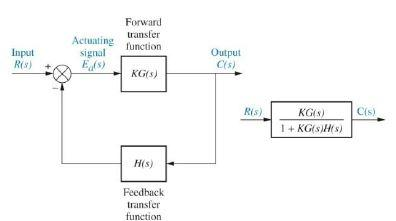

**Characteristic equation** is 


$$1+KG(s)H(s)=0 \qquad \Leftrightarrow
\qquad KG(s)H(s)=-1$$


If We let $G(s)H(s)=P(s)=\frac{Z_m(s)}{P_n(s)}=\frac{\Pi_{i=1}^{m}(s+z_i)}{\Pi_{k=1}^{n}(s+p_k)}$

then the char. eqn is $1+K\frac{\Pi_{i=1}^{m}(s+z_i)}{\Pi_{k=1}^{n}(s+p_k)}=0$

which is equivalent to 


$$\prod_{k=1}^{n}(s+p_k)+K\prod_{i=1}^{m}(s+z_i)=0\quad \stackrel{K=0}{\longrightarrow} \qquad \prod_{k=1}^{n}(s+p_k)=0$$


Conclusion: The root locus **start** at OL system poles with $K=0$


$$\frac{1}{K}\prod_{k=1}^{n}(s+p_k)+\prod_{i=1}^{m}(s+z_i)=0\quad \stackrel{K=\infty}{\longrightarrow} \qquad \prod_{k=1}^{n}(s+z_i)=0$$


Conclusion: The root locus **end** at OL system zeros with $K\rightarrow \infty$

## Example 1

a)$G(s)H(s)=\frac{s-1}{(s+1)(s+2)}$     b) $G(s)H(s)=\frac{1}{(s+1)(s^2+1)}$

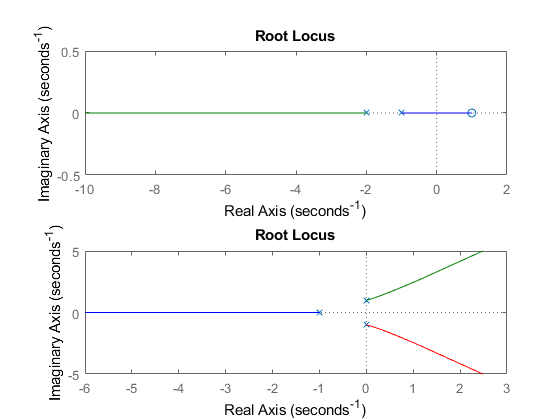

GH_a=zpk(1,[-1,-2],1);
figure(1)
subplot(2,1,1)
rlocus(GH_a)
GH_b=zpk([],[-1,+1j,-1j],1);
subplot(2,1,2)
rlocus(GH_b)

c) $G(s)H(s)=\frac{(s+1)(s+2)}{(s^2+1)}$   d) $G(s)H(s)=\frac{1}{s^2+1}$

GH_c=zpk([-1,-2],[1j,-1j],1);
figure(2)
subplot(2,2,1)
rlocus(GH_c)
GH_d=zpk([],[+1j,-1j],1);
subplot(2,2,2)
rlocus(GH_d)

e) $G(s)H(s)=\frac{1}{(s+1)(s+2)(s+3)(s+4)}$   f) $G(s)H(s)=\frac{(s+1)(s+2)}{(s-1)(s-2)}$

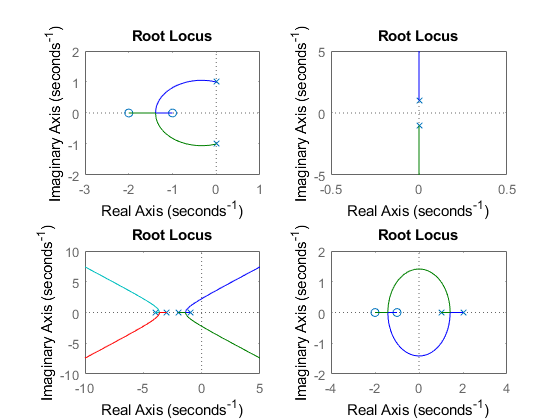

GH_e=zpk([],[-1,-2,-3,-4],1);
subplot(2,2,3)
rlocus(GH_e)
GH_f=zpk([-1,-2],[1,2],1);
subplot(2,2,4)
rlocus(GH_f)

## Example 2


$$G(s)H(s)=\frac{(s-1)(s-2)(s+2)}{(s-1+i)(s-1-i)(s+1)}$$


GH_2 = zpk([1,2,-2],[1-1j,1+1j,-1],1)


GH_2 =
 
   (s-1) (s-2) (s+2)
  --------------------
  (s+1) (s^2 - 2s + 2)
 
Continuous-time zero/pole/gain model.



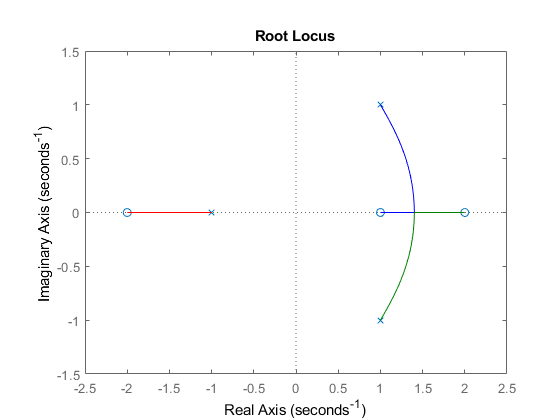

figure(3)
rlocus(GH_2)

## Example 3

For a unity-feedback system with a forward transfer function $G(s)=\frac{K}{s(s+6)(s+9)}$, plot the root locus and find breakaway points, asymptotes, and $j\omega$-axis crossing points.

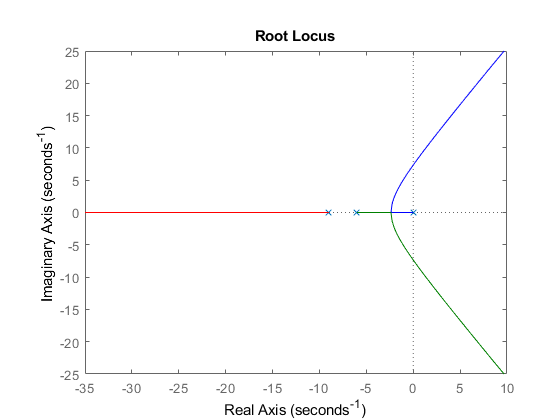

GH_3 = zpk([],[0,-6,-9],[1]);
rlocus(GH_3)

## Assignment

Given the feedback system shown below.

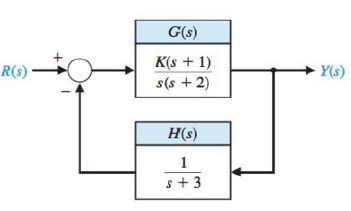

a) Determine the characteristic equation for the closed loop system

b) Determine the number of asymptotes and their angles

c) Sketch the RL

d) Determine the break-away point

e) Determine the range of K for which the system is stable